load bmsegment.mat
cc = bwconncomp(segment, 6)

cc = struct with fields:
    Connectivity: 6
       ImageSize: [300 300 300]
      NumObjects: 6038
    PixelIdxList: {1×6038 cell}


lm = labelmatrix(cc)

lm = 300×300×300 uint16 array
lm(:,:,1) =

    0    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    0    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1    0    0    0    0    0   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10   10    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    1    1    1    1    1    1    1    1    1    1    1    1    1    1    1  

rgb = label2rgb(lm(:,:,200), 'jet', 'w', 'shuffle')

rgb = 300×300×3 uint8 array
rgb(:,:,1) =

   255     0     0   255   255   255     0   255     0     0   255   255   255   255     0     0     0   255   255     0     0   255     0     0     0     0     0     0     0     0     0     0     0   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255     0     0   255     0     0    

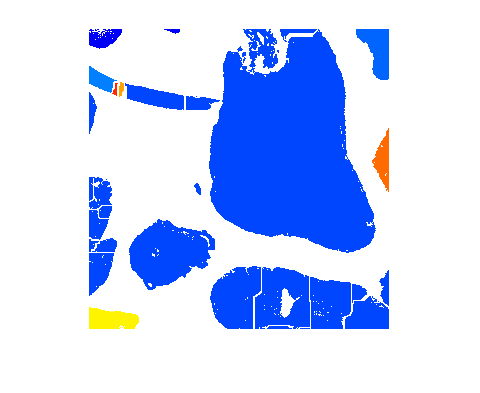

imshow(rgb)